# diverse formler og utrekningar for Transferfunksjonar.

Laget av Sverre K.H. Kvist.

####      *Førsteordensfunksjon*                            *Andrordensfunksjon*

        
$$G{\left(s\right)}=\frac{K}{\textrm{𝜏}s+1}$$
                                            
$$G{\left(s\right)}=\frac{K\cdot {\textrm{𝜔}}_n^2 }{s^2 +2\textrm{𝜁}{\textrm{𝜔}}_n +{\textrm{𝜔}}_n^2 }$$


####  Startverdi med S i origo


$$\textrm{Startverdi}=20\log {\left(\frac{1}{\alpha \;}\right)}+20\log {\left(K\right)}$$



$$\alpha :a\;\textrm{point}\;\textrm{smaller}\;\textrm{that}\;\textrm{the}\;\textrm{smallest}\;\textrm{pole}\ldotp$$


clc, clear, close all;
k=12;
alfa=0.1;
 
Startverdi=20*log10(1/alfa)+20*log10(k)

Startverdi = 41.5836

#### Max oversving


$$\textrm{OS}=\;e^{\frac{-\zeta \cdot \pi \;}{\;\sqrt{\;1-\zeta {\;}^{2\;} \;}}\;}$$


clc, clear, close all;
zeta = 0.355;
 
Overshoot=exp((-zeta*pi)/(sqrt(1-zeta^2)))

Overshoot =    0.303319735256283

#### Dempefaktor som funksjon av OS


$$\zeta =\frac{-\ln \left(\textrm{OS}\right)}{\sqrt{\;\pi {\;}^{2\;} +\ln^2 \left(\textrm{OS}\right)}}$$


clc, clear, close all;
os=0.2;
 
zetaa = (-log(os))/(sqrt(pi^2+log(os)^2))

zetaa =    0.455949810769126

#### Utrekning for frekvens


$$\omega_{n\;} =\frac{\pi }{\;T_{p\cdot \;} \sqrt{\;1-{\zeta \;}^2 }}\;$$


clc, clear, close all;
tp =1.21;
zeta=0.33;
 
Omega=(pi)/tp*(sqrt(1-zeta^2))

Omega =    2.450912033995051

#### Tidspunkt for max oversning


$$T_p =\frac{\textrm{𝜋}}{{\textrm{𝜔}}_n \cdot \;\sqrt{1\ -{\textrm{𝜁}}^2 }}$$


clc, clear, close all;
omega =2;
zeta=0.7;
 
Tp=(pi)/(omega*sqrt(1-zeta^2))

Tp =    2.199554812475247

#### Innsvingingstid ($5\tau$)


$$T_s =5\cdot \frac{1}{\zeta \;\omega \;}\;$$


clc, clear, close all;
omega=3.4;
zeta=23;
 
Ts=5*(1/zeta*omega)

Ts =    0.739130434782609

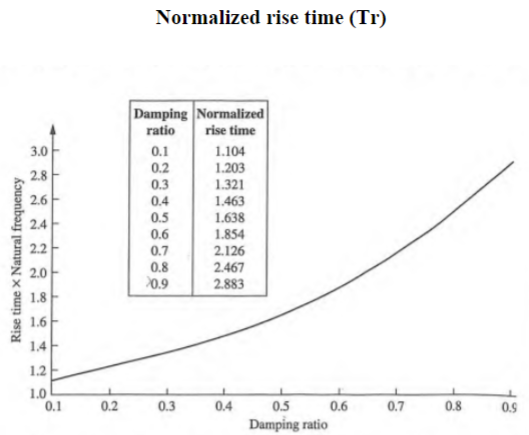


$$\omega {\;}_{n\;} =\frac{\textrm{normalized}\;\textrm{rise}\;\textrm{time}\;\left(\textrm{Tr}\right)}{\textrm{Wanted}\;\textrm{Rise}\;\textrm{time}}$$


clc,clear, close all;
Tr=1.57;
WTr=0.3;
 
frekvens= Tr/WTr

frekvens =    5.233333333333333

#### Finner nye punkt.


$$-\omega {\;}_n \;\zeta \pm j\omega {\;}_n \sqrt{1-\zeta^2 }$$


omega =5.233;
zeta=0.4559;
 
reell=-omega*zeta

reell =   -2.385724700000000

imaginer=omega*sqrt(1-zeta^2)

imaginer =    4.657532249572719

## Marginer og frekvenser.

**Choose a K such that the GM will be **$\alpha \;$


$$K=10^{\frac{\left(G_m -\alpha \;\right)\textrm{dB}}{20}} \;$$


clc, clear, close all;
gm=32.6;
alpha=12;
 
K=10^((gm-alpha)/20)

K =   10.715193052376065

**Choose a K such that the PM will be **$\alpha \;\;$

at $K=10^{\frac{\left(-\beta \;\right)}{20}}$ PM = $\alpha \;$


$$\left(\beta \;\right):\textrm{gain}\;\textrm{margin}\;\textrm{at}\;\textrm{the}\;\textrm{point}\;\textrm{where}\;\textrm{you}\;\textrm{have}\;\textrm{the}\;\textrm{desiered}\;\textrm{phase}\ldotp$$


clc, clear, close all;
beta=0;
 
k=10^((-beta)/20)

k =      1

**Gain Margin(GM):** The gain margin of a system defines by how much the system gain can be increased so that the system moves on the edge of stability.


$$G_{m\;} =\frac{1}{\left|G\left(j\omega \right)H\left(j\omega \right){\left|\right.}_{\omega =\omega \;\textrm{pc}} \right.}$$


**Phase crossover frequency (**$\omega {\;}_{\textrm{pc}}$**): **Is the frequency at wich the phase angle of G(s)H(s) is -180


$$\angle \;G\left(j\omega \;\right)\;H\left(j\omega \;\right){\left|\right.}_{\omega =\omega \;\textrm{pc}}$$


**Phase margin(PM): ** The Phase margin of the system defines by how much the phase of the system can increase to make the system unstable.


$$\textrm{PM}={180}^{\circ } +\angle \;G\left(j\omega \;\right)\;H\left(j\omega \;\right){\left|\right.}_{\omega =\omega \;\textrm{pc}} =-{180}^{\circ }$$


**Gain crossover frequency:(**$\omega {\;}_{\textrm{GC}}$**):** Is the frequency at wich the magnitude og G(s)H(s) is unity


$$\left|G\left(j\omega \;\right)H\left(j\omega \;\right){\left|\right.}_{\omega =\omega \;\textrm{Gc}} =1\right.$$


## Calculation:


$$G\left(S\right)=\frac{100}{\;{\left(s+1\right)}^{3\;} }=\frac{100}{s^3 +1+3s\left(1+s\right)}$$



$$G\left(j\omega \;\right)=\frac{100\left\lbrack \left(1-3\omega {\;}^2 \right)-j\left(3\omega -\omega {\;}^3 \right)\right\rbrack }{\;{\left(1-3\omega {\;}^2 \right)}^2 +{\left(3\omega -\omega {\;}^{3\;} \right)}^2 }\;\;\;\;\;$$
